Prob1

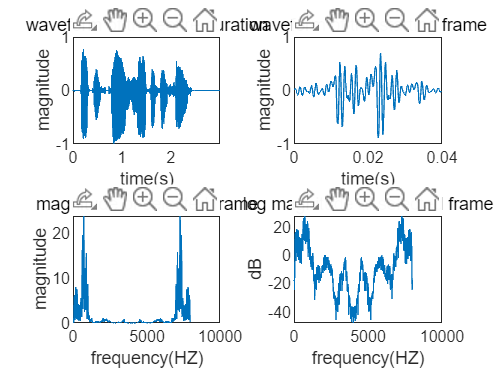

start1 = 7000;
start2 = 1000;
STSA_SingleFrame('s5.wav', start1, 40)   % 最后一个参数是frame lengt(msec)

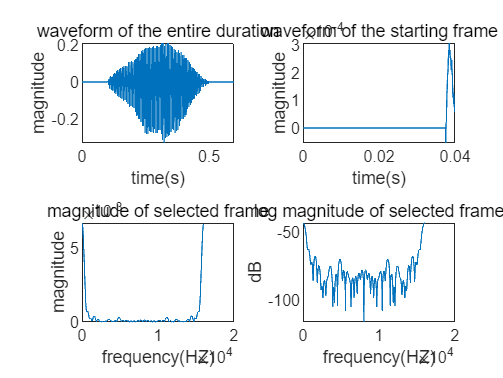

STSA_SingleFrame('vowel_iy_100hz.wav', start2, 40);

Prob2

四个不同的frame length，对每个frame length画时域，magnitude和db

i = 1

frame_length = 40

frame_select =     0.2087
    0.2487
    0.3318
    0.3948
    0.3538
    0.0487
   -0.5246
   -0.8805
   -0.9282
   -0.8256


t_frame =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049


i = 2

frame_length = 80

frame_select =     0.2087
    0.2487
    0.3318
    0.3948
    0.3538
    0.0487
   -0.5246
   -0.8805
   -0.9282
   -0.8256


t_frame =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


i = 3

frame_length = 160

frame_select =     0.2087
    0.2487
    0.3318
    0.3948
    0.3538
    0.0487
   -0.5246
   -0.8805
   -0.9282
   -0.8256


t_frame =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


i = 4

frame_length = 320

frame_select =     0.2087
    0.2487
    0.3318
    0.3948
    0.3538
    0.0487
   -0.5246
   -0.8805
   -0.9282
   -0.8256


t_frame =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


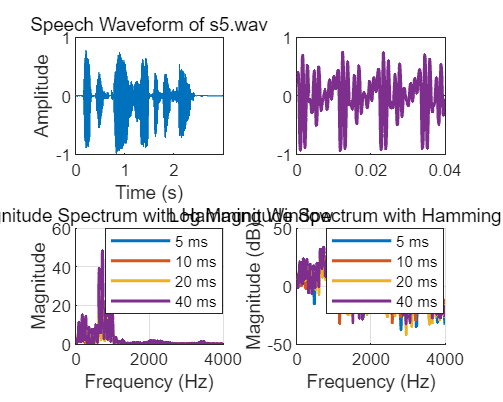

clc, clear all;
frame_length = [5, 10, 20, 40];   % msec
start = 7000;
% STSA_MultiLength(4, 's5.wav', start, frame_length);
STSA_MultiLength2(4, 's5.wav', start, frame_length);

function STSA_SingleFrame(filename, startsmp, framelength)   % framelength is in msec
    [y, fs] = audioread(filename);
    frame_length = framelength*fs*1e-3;   % frame length in samples
    win = hamming(frame_length);
    frame_start = y(startsmp:startsmp+frame_length-1) .* win;   % 列向量
    
    t_whole = (0:length(y)-1)/fs;
    t_frame = (0:frame_length-1)/fs;
    nfft = 2^nextpow2(frame_length);   % zero-padding
%     f = fs * (0 : nfft/2) / nfft
    f = linspace(0, fs, nfft);
    spectrum = abs(fft(frame_start, nfft));
    log_spectum = 20*log10(spectrum);
    
    
    % plot
    figure
    subplot(2,2,1)
    plot(t_whole, y), title('waveform of the entire duration'), xlabel('time(s)'), ylabel('magnitude')
    subplot(2,2,2)
    plot(t_frame, frame_start), title('waveform of the starting frame'), xlabel('time(s)'), ylabel('magnitude')
    % stft of the selected frame
    subplot(2,2,3)
    plot(f, spectrum), xlabel('frequency(HZ)'), ylabel('magnitude'), title('magnitude of selected frame')
    subplot(2,2,4)
    plot(f, log_spectum), xlabel('frequency(HZ)'), ylabel('dB'), title('log magnitude of selected frame')
end


% 矩形窗不知道为什么第二个图只有length=40的情况
function STSA_MultiLength(num, filename, startsmp, framelengths)
    [y, fs] = audioread(filename);
    t_whole = (0:length(y)-1)/fs;
    flag = 0;
    
    % 情况一
    % 创建图形窗口，hamming窗
    figure;
    clf;
    
    % 初始化颜色和图例
    colors = lines(num); % 获取不同颜色
    legends = cell(num, 1);
    
    subplot(2,2,1);
    plot(t_whole, y);
    title('Speech Waveform of s5.wav');
    xlabel('Time (s)');
    ylabel('Amplitude');
    xlim([t_whole(1) t_whole(end)]);
    
    % 初始化其他子图的保持状态
    subplot(2,2,2); cla; 
    hold on;
    subplot(2,2,3); cla; hold on;
    subplot(2,2,4); cla; hold on;
    
    for i = 1:num
        frame_length = round(framelengths(i)*fs*1e-3);
        frame_select = y(startsmp:startsmp+frame_length-1) .* hamming(frame_length);
        nfft = max(1024, 2^nextpow2(frame_length)); 
        
        % 短时傅里叶分析
        spectrum = abs(fft(frame_select, nfft));
        spectrum = spectrum(1:nfft/2+1); 
        log_spectrum = 20*log10(spectrum);
        
        f = linspace(0, fs/2, nfft/2+1);
        t_frame = (0:frame_length-1)/fs + t_whole(startsmp);
        
        % 图例标签
        legends{i} = sprintf('%d ms', framelengths(i));
       
        % plot
        subplot(2,2,2);
        plot(t_frame, frame_select, 'Color', colors(i,:), 'LineWidth', 1.5);
        hold on
        subplot(2,2,3);
        plot(f, spectrum, 'Color', colors(i,:), 'LineWidth', 1.5);
        subplot(2,2,4);
        plot(f, log_spectrum, 'Color', colors(i,:), 'LineWidth', 1.5);
        if num==4
            flag = 1;
        end
    end
    
    % 添加图例和标签
    subplot(2,2,2);
    title('Frame Waveform with Hamming Window');
    xlabel('Time (s)');
    ylabel('Amplitude');
    legend(legends, 'Location', 'best');
    grid on;
    
    subplot(2,2,3);
    title('Magnitude Spectrum with Hamming Window');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    legend(legends, 'Location', 'best');
    grid on;
    xlim([0 fs/2]);
    
    subplot(2,2,4);
    title('Log Magnitude Spectrum with Hamming Window');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    legend(legends, 'Location', 'best');
    grid on;
    xlim([0 fs/2]);
    set(gcf, 'Position', [100, 100, 1000, 800]);
    
    
    
    
    % 情况二
    % 创建图形窗口，rect窗
    if flag == 1
        figure
        clf;
        % 初始化颜色和图例
        colors = lines(num); % 获取不同颜色
        legends = cell(num, 1);
        
        subplot(2,2,1);
        plot(t_whole, y);
        title('Speech Waveform of s5.wav');
        xlabel('Time (s)');
        ylabel('Amplitude');
        xlim([t_whole(1) t_whole(end)]);
        
        % 初始化其他子图的保持状态
        subplot(2,2,2); cla; hold on;
        subplot(2,2,3); cla; hold on;
        subplot(2,2,4); cla; hold on;
        
        for k = 1:num
            frame_length = round(framelengths(k)*fs*1e-3);
            frame_select = y(startsmp:startsmp+frame_length-1) .* rectwin(frame_length);
            nfft = max(1024, 2^nextpow2(frame_length)); 
            
            % 短时傅里叶分析
            spectrum = abs(fft(frame_select, nfft));
            spectrum = spectrum(1:nfft/2+1); 
            log_spectrum = 20*log10(spectrum);
            
            f = linspace(0, fs/2, nfft/2+1);
            t_frame = (0:frame_length-1)/fs + t_whole(startsmp);
            
            % 图例标签
            legends{k} = sprintf('%d ms', framelengths(k));
           
            % plot
            subplot(2,2,2);
            plot(t_frame, frame_select, 'Color', colors(k,:), 'LineWidth', 1.5);
            hold on
            subplot(2,2,3);
            plot(f, spectrum, 'Color', colors(k,:), 'LineWidth', 1.5);
            hold on
            subplot(2,2,4);
            plot(f, log_spectrum, 'Color', colors(k,:), 'LineWidth', 1.5);
            hold on
        end
        
        % 添加图例和标签
        subplot(2,2,2);
        title('Frame Waveform with Rectangle Window');
        xlabel('Time (s)');
        ylabel('Amplitude');
        legend(legends, 'Location', 'best');
        grid off;
        
        subplot(2,2,3);
        title('Magnitude Spectrum with Rectangle Window');
        xlabel('Frequency (Hz)');
        ylabel('Magnitude');
        legend(legends, 'Location', 'best');
        grid on;
        xlim([0 fs/2]);
        
        subplot(2,2,4);
        title('Log Magnitude Spectrum with Rectangle Window');
        xlabel('Frequency (Hz)');
        ylabel('Magnitude (dB)');
        legend(legends, 'Location', 'best');
        grid on;
        xlim([0 fs/2])
        set(gcf, 'Position', [100, 100, 1000, 800]);
    end
end


% 针对上面函数的问题进行补丁:但好像还是不行，换成hamming没事，矩形窗有问题
function STSA_MultiLength2(num, filename, startsmp, framelengths)
    [y, fs] = audioread(filename);
    t_whole = (0:length(y)-1)/fs;
    
    % 情况一
    % 创建图形窗口，hamming窗
    figure;
    clf;
    
    % 初始化颜色和图例
    colors = lines(num); % 获取不同颜色
    legends = cell(num, 1);
    
    subplot(2,2,1);
    plot(t_whole, y);
    title('Speech Waveform of s5.wav');
    xlabel('Time (s)');
    ylabel('Amplitude');
    xlim([t_whole(1) t_whole(end)]);
    
    % 初始化其他子图的保持状态
    subplot(2,2,2); cla; 
    hold on;
    subplot(2,2,3); cla; hold on;
    subplot(2,2,4); cla; hold on;
    
    for i = 1:num
        i
        frame_length = round(framelengths(i)*fs*1e-3)
        frame_select = y(startsmp:startsmp+frame_length-1) .* rectwin(frame_length)
        nfft = max(1024, 2^nextpow2(frame_length)); 
        
        % 短时傅里叶分析
        spectrum = abs(fft(frame_select, nfft));
        spectrum = spectrum(1:nfft/2+1); 
        log_spectrum = 20*log10(spectrum);
        
        f = linspace(0, fs/2, nfft/2+1);
        t_frame = (0:frame_length-1)/fs 
        
        % 图例标签
        legends{i} = sprintf('%d ms', framelengths(i));
       
        % plot
        subplot(2,2,2);
% figure
        plot(t_frame, frame_select, 'Color', colors(i,:), 'LineWidth', 1.5);
        hold off
%         hold on;
        subplot(2,2,3);
        plot(f, spectrum, 'Color', colors(i,:), 'LineWidth', 1.5);
        hold on
        subplot(2,2,4);
        plot(f, log_spectrum, 'Color', colors(i,:), 'LineWidth', 1.5);
        hold on
    end
        % 添加图例和标签
%     subplot(2,2,2);
%     title('Frame Waveform with Hamming Window');
%     xlabel('Time (s)');
%     ylabel('Amplitude');
% %     legend(legends, 'Location', 'best');
%     grid on;
    
    subplot(2,2,3);
    title('Magnitude Spectrum with Hamming Window');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    legend(legends, 'Location', 'best');
    grid on;
    xlim([0 fs/2]);
    
    subplot(2,2,4);
    title('Log Magnitude Spectrum with Hamming Window');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    legend(legends, 'Location', 'best');
    grid on;
    xlim([0 fs/2]);
    set(gcf, 'Position', [100, 100, 1000, 800]);
end
